# DC Motor Dynamic Modeling and Position Control

This Live Script is dedicated to validating theoretical approaches for monophasic DC motor control through experiments and simulations. Focused on confirming the efficacy of control methodologies, including reduced-order modeling, state-space representation, transfer function analysis, parameter estimation, and a Proportional-Integral (PI) control strategy, this script serves as a practical guide for engineers and researchers. By integrating real-time experimentation with theoretical analysis and simulations, it aims to bolster confidence in DC motor control techniques for industrial applications. There are already many works with regards the control of  [DC motors](https://www.mathworks.com/videos/series/brushless-dc-motors.htmlhttps://www.mathworks.com/videos/series/brushless-dc-motors.html). However, in this case a simple monophasic DC motor set that includes a reduction and encoder is selected to perform parameter identification, simulations and experiments. 

## 1. Reduced DC Motor Modeling and Transfer Function Representation

A simple model that considers the mechanical dynamics of a DC motor is proposed using a second-order differential equation.

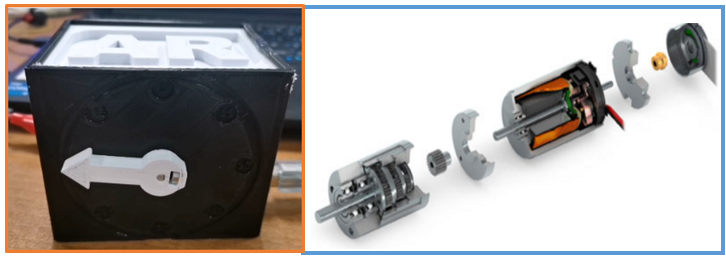DC Lab experimental platform

The DC motor reduced dynamics:


$$\Gamma = KV = J\ddot{\theta} + v\dot{\theta} + \tau^{nlf}

$$


where

$\Gamma
$: Motor torque.

$K
$: Motor constant.

$v$: Viscous friction.

$J
$: Motor inertia.

$\tau^{nlf}
$: Static Coulomb friction.

$V$: Input (voltage).

Upon compensating for the static Coulomb friction and applying the Laplace transform to the differential equation,  the following representation in s-domain is obtained


$$KV(s) = Js^2\theta(s) + v\theta(s)
$$


Then using this equation we obtain the following transfer function:


$$ \frac{\theta(s)}{V(s)}= \frac{\frac{k}{J}}{s(s + \frac{v}{J})}
$$
 
$$= \frac{A}{s(s + B)}
$$


where   $A=\frac{k}{J}$  $B=\frac{v}{J}$

## 2. State-space Representation

State-space representation offers a framework for modeling and analyzing dynamical systems using linear algebra. The depicted equations describe the relationship between the input, system states, and output, capturing the dynamics of the DC motor in matrix form. Considering the system differential equation:


$$KV = J\ddot{\theta} + v\dot{\theta}$$



$$\ddot{\theta} = \frac{kV}{J} - \frac{v}{J}\dot{\theta}$$


The state-space representation general format:


$$\dot{x} = Ax + Bu$$
 


$$y = Cx + Du$$


where

$A
$*: State Matrix *

$B$*: Input Matrix*

$C$*: Output Matrix*

$D$*: Direct Feedthrough Matrix*

By considering the state vector $x = \left[\begin{array}{c} \theta \\ \dot{\theta} \end{array}\right]
$ and $\dot{x} = \left[\begin{array}{c} \dot{\theta} \\ \ddot{\theta} \end{array}\right]
$, and with the input being the voltage $V
$ and the output being the angular speed $\dot{\theta}$: the following state and output equations are obtained:


$$\dot{x} = \left[\begin{array}{cc} 0 & 1 \\ 0 & -\frac{v}{J} \end{array}\right]x + \left[\begin{array}{c} 0 \\ \frac{k}{J} \end{array}\right]V(t)
$$



$$y = \left[\begin{array}{cc} 0 & 1 \end{array}\right]x + \left[\begin{array}{c} 0 \end{array}\right]V(t)
$$


This state-space representation can be simulated in Simulink using the following diagram. But in our case, there is not any relationship between the input and the output, and therefore, $D$=0:

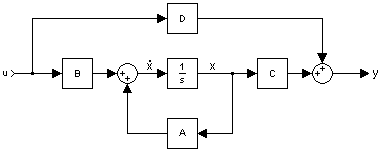

## 3. Real-time Implementation (in case you have a DC motor platform)

In the real-time process, we initiate with a system identification technique for the actual system. This begins by gathering input and output data from the genuine system. Subsequently, initial estimates for parameters $A$ and $B$ are set. Leveraging the Parameter Estimator tool in Simulink, precise values for $A$ and $B$ are determined. Once acquired, this dynamical model is primed for the application of various control strategies.

*Real-time data collection:  *[*Video*](https://www.youtube.com/watch?v=DnpoiHNvwhs)*   This is a closed-loop method for data collection. Multiples steps inputs are used as references. Controller's input and output are recorded. *

By using this Simulink you can collect the data if you have a DC motor conected to the digital card and the computer.

isPlatform=false; %select if the platform exist
matlab_version="2022b";%Enter your matlab version

if isPlatform
    if matlab_version == "after2022b"
    open_system('Real_Data__Collection.slx'); %%For matlab versions after 2022b 
    else
    open_system('Real_Data__Collection_2022b.slx');%% For matlab 2022b version
    end
end

After running the program use this code to simulate the collected data then save it:

 if isPlatform   
    Look_Up_table=double(Look_Up_table)';
    Time_segment=Time_segment';
    input_signal=input_signal';
    figure (1);plot(Time_segment,input_signal,'r',Time_segment,Look_Up_table,'b');grid on;
    hold on; 
    hold off;
    xlabel('Time (s)');
    ylabel('Position in counts');
    save Collected_Data_new Look_Up_table Time_segment input_signal
 end

Note that you should select the boxes if the platform exist and make sure to simulate first before saving the collected data.

## 4. DC Parameter Estimation Process (work with collected data without the DC motor platform)

Previously collected data will be loaded and used for DC parameter estimation. Remember to name data with the correct names as written below.

load('Collected_Data.mat');
Look_Up_table=double(Look_Up_table)';% for output data
Time_segment=Time_segment';% for the time vector
input_signal=input_signal';% for input data

The dipicted Simulink model is equivalent to the model implemented for real time experiments. This data is obtained in order to compare the real sistem and a simulated system, and to estimate the best A and B parameters.

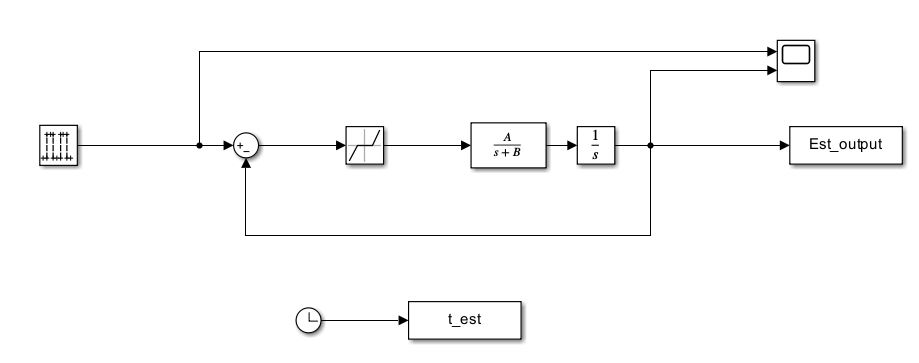

Plotting the collected data

The collected data are the input reference and measured output after performing some experiments using a closed-loop proportional controller.

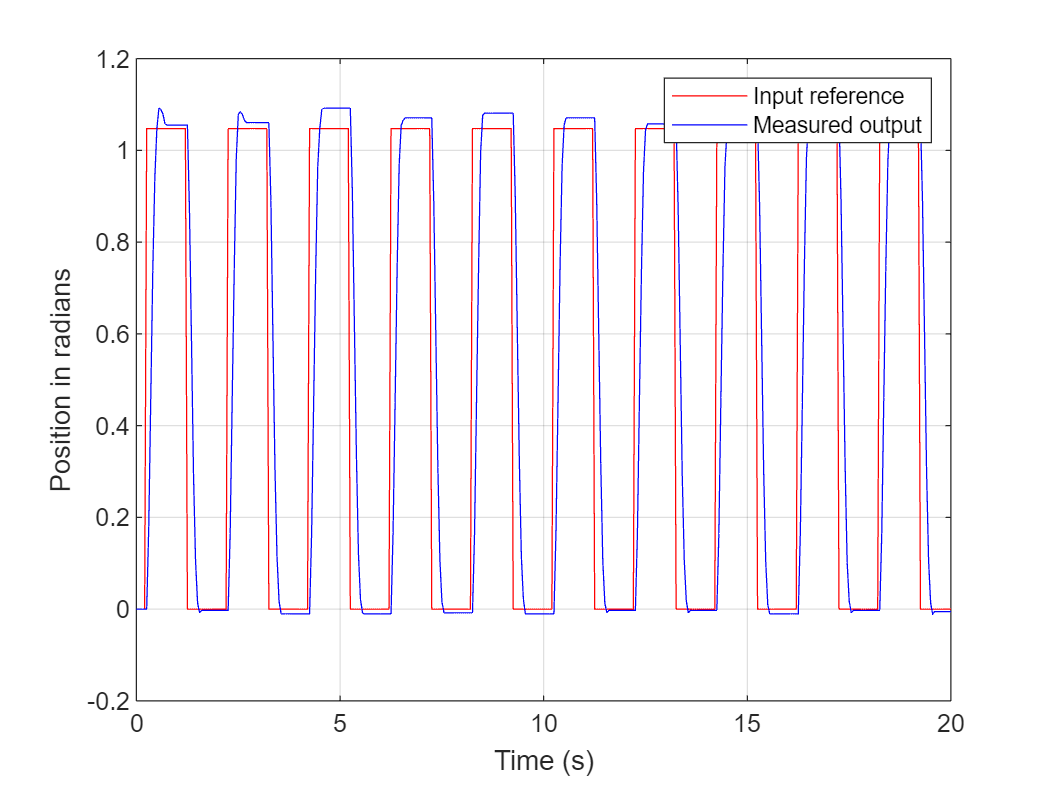

figure (1);plot(Time_segment,input_signal,'r',Time_segment,Look_Up_table,'b');grid on;
xlabel('Time (s)');
ylabel('Position in radians');legend('Input reference', 'Measured output');

Look_Up_table=double(Look_Up_table)';%we are retransposing them to make them ready to use for parameter estimation
Time_segment=Time_segment';
input_signal=input_signal';
A=1100; % a random initial value for A
B=55;   % a random initial value for B

% the running system for collecting a data from the simulation enviroment
if matlab_version == "after2022b"
    open_system('Sim_System_Param_Estimator.slx'); %%For matlab versions after 2022b 
else
    open_system('Sim_System_Param_Estimator_2022b.slx');%% For matlab 2022b version
end

By running the Parameter Estimator app in Simulink we can acquire the real $A$ and $B$ parameters as shown in the videos. Using $A$ and $B$ values and the following Simulink diagram, we can start the control design process to identify the controller's gains for a Proportional Integral (PI) Regulator. The following video shows how the Parameter Estimator is used [Video](https://www.youtube.com/watch?v=EWHgx8m1h5s).

save estimation_for_AB A B  %This line to be used after the parameter estimation to save the results

## 5. DC Motor Position Control using PI control

Given a DC motor with the transfer function:

#### 
$$G(s) = \frac{A}{s(s+B)}
$$


And if we want to use a PI controller of the form:

#### 
$$C(s) = K_P + \frac{K_I}{s} = K_P\left(1 + \frac{1}{T_Is}\right)
$$


Where $K_p
$ is the proportional gain and $K_i$ is the integral gain, $T_i=\frac{K_p}{K_i}$ is the integral time constant.

The closed-loop transfer function with the PI controller will be:

#### 
$$T(s) = \frac{G(s)C(s)}{1 + G(s)C(s)}
$$


Given the original poles of the system are at $s=0$ and $s=-B$ , introducing a PI controller adds an integrator which introduces an additional pole at $s=0$.

**PI Controller's tuning**

In this case we will use pole placement considering the following criteria:

- The poles will be name using a single parameter $\alpha$ to place 3 multiple real poles .

- The poles must be placed as far as possible on the left side of the s-plane for faster response considering system constraints. constraints

By considering these conditions and using the pole placement method we end up with this equation:


$$s^3 + B s^2 + A K_p s + A K_i = (s + \alpha)^3
$$


So by substituting $A$ and $B$ values and comparing the two sides we reach these values for $\alpha$,$K_p$ and $K_i$:


$$\alpha=\frac{B}{3}$$
  
$$K_p=\frac{3\alpha^2}{A}$$
 
$$K_i=\frac{\alpha^3}{A}$$


%load('estimated_AB.mat'); %load this data if you cannot do the parameter estimation
alpha=B/3;
Kp=(3*(alpha^2))/A; 
Ki=((alpha^3)/A);

Using the following Simulink you can check the response of these controllers. The following video shows the experimental and simulated PI position controller [Video.](https://www.youtube.com/watch?v=te9CZy4DAIE)

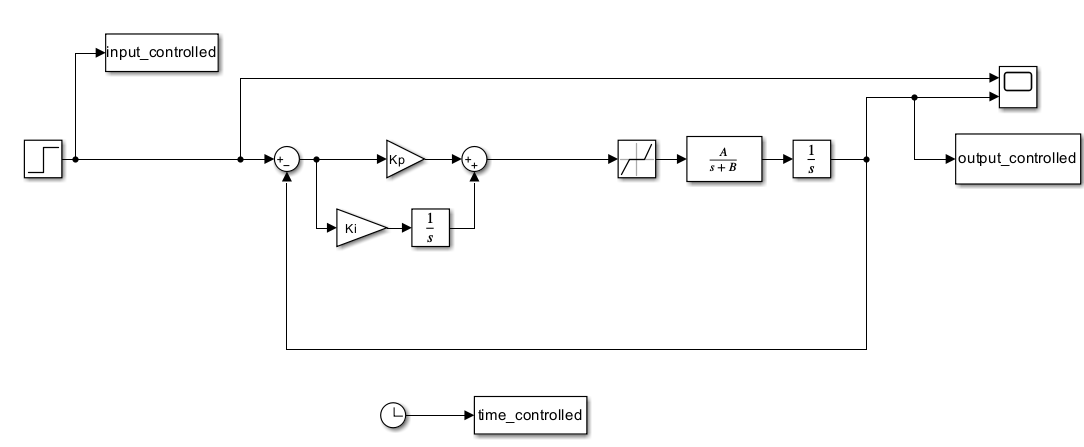

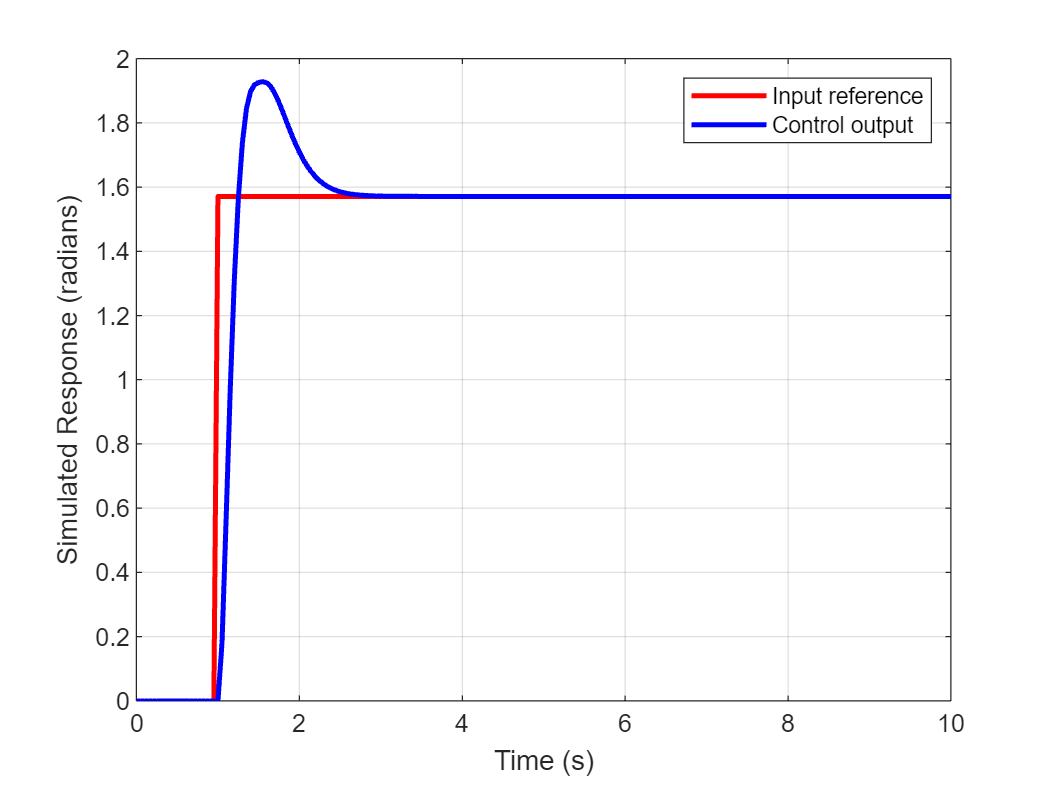

open_system('sim_closedloop_position_controller_2022b'); 
sim sim_closedloop_position_controller_2022b ;
figure (1);plot(time_controlled,input_controlled,'r',time_controlled,output_controlled,'b','LineWidth',2);grid on;
xlabel('Time (s)');
ylabel('Simulated Response (radians)');legend('Input reference', 'Control output');

## 6. Real-time Experiment

If you have the platform and want to use the PI position controller the following Simulink can be used:

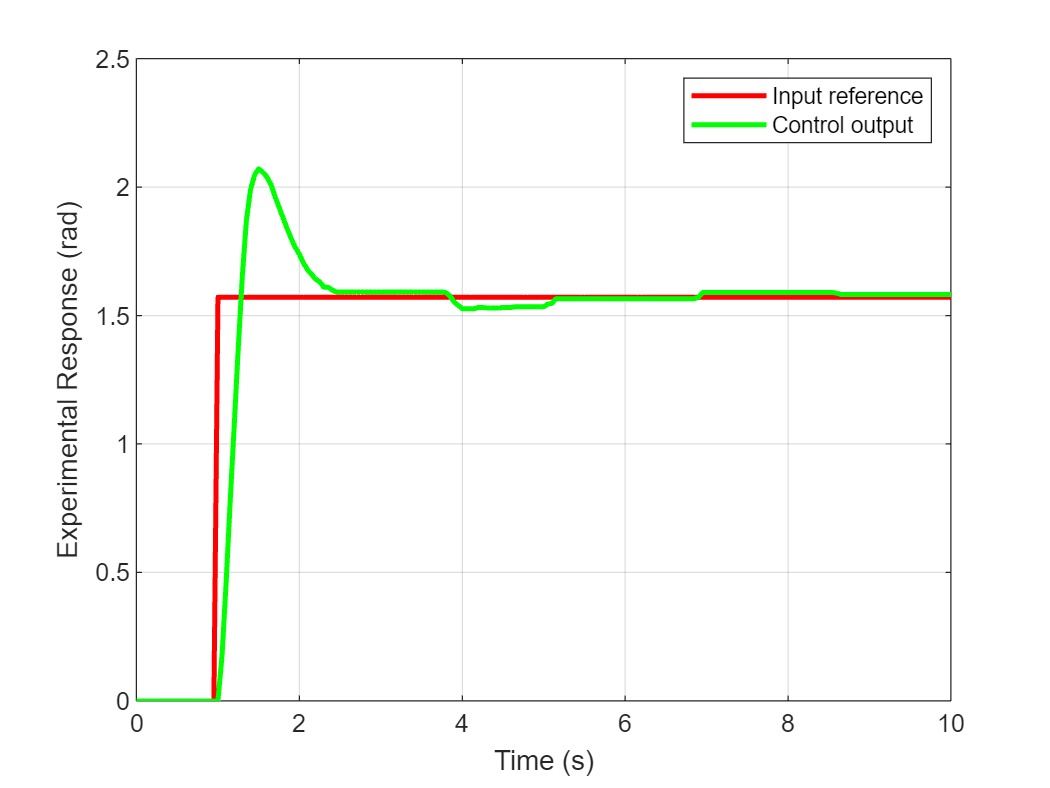

% open_system('Real_System_position_controller');
% open_system('Real_System_position_controller_2022b');
load('Real_controlled_data.mat');
figure (2);plot(tr,input_r,'r',tr,output,'g','LineWidth',2);grid on;
xlabel('Time (s)');
ylabel('Experimental Response (rad)'); legend('Input reference', 'Control output');

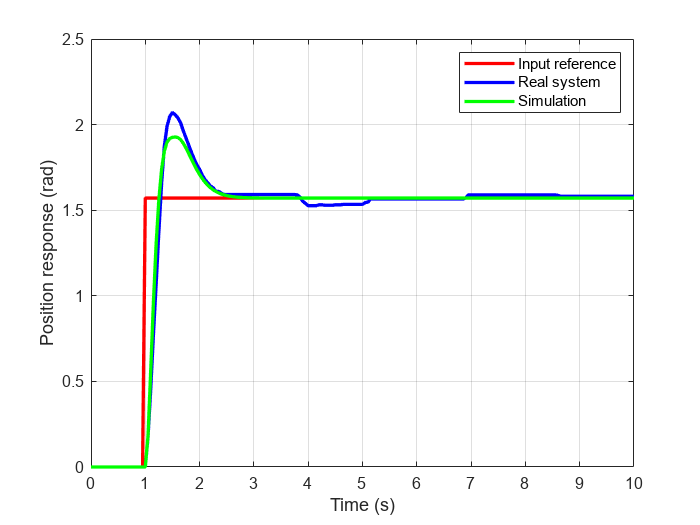

figure(3);plot(tr,input_r,'r',tr,output,'b',tr,output_controlled,'g','LineWidth',2);grid on;
legend('Input reference', 'Real system', 'Simulation');
hold on; 
xlabel('Time (s)');
ylabel('Position response (rad)');
hold off;

## 7. Homework

Work with the parameter estimator toolbox and the measured data provided in Section 4.

Use the PI controller provided and the Simulink file, and study the pole placement method in the explanation to design other possible controllers, with $\alpha$ as a controller tunning parameter, see Section 5. Test the controllers by changing only the parameter $\alpha$. 

It is a work by